# ECSE 343: Numerical Methods for Engineers- Assignment 1

Due Date:  Feb 6th

Student Name: Deniz Karakus

Student ID: 261114510

## Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

## Please submit this **.mlx** file along with the **PDF** copy of this file.

## **Question 1:  Fixed Point Number Repersentation (15 marks)**

One possible way to store represent numbers in computer is to use **fixed **point integer method. Suppose we have a 64-bit fixed point integer representation, where we use 31bits for the integer part and 32 bits for the fraction part and 1 bit is reserved for the the sign bit. The visual representation of our number is shown below, 

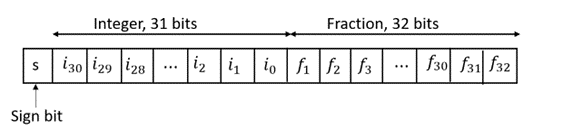

Using the above scheme any number can be represented as following


$$i_{30} 2^{30} +\ i_{29} 2^{29} +\ldots+\ i_1 2^1 +i_2 2^0 +f_1 2^{-1} +f_2 2^{-2} +\ldots+f_{31} 2^{-31} +f_{32} 2^{-32}$$


For example, 43.625  can be represented as,

Where, 0 is used to represent the positive sign and  0000...0000101011 is a 31 bit binary value for decimal 43 and 1010000...0000 is a 32 bit binary value for fractional 0.625.

    a) Find the smallest and the largest positive number that can be represented in this format.

**    smallest positive number --> set every bit to zero except the LSB. This makes smallest positive number = 2^-32**

**    largest positive number --> set the sign bit to 0 and all the integer bits and fraction bits to 1. For the integer, we get 2^(31) - 1. For the decimal part, we get 1-2^(-32). When we add the             **

**    integer part and decimal part, we get 2^(31) - 2^(-32). Therefore this is the largest positive number.**

    b) Give an upper bound on the *absolute *error due to rounding on numbers stored using the above **64-bit fixed point** representation.

**    distance between two adjacent stored values  = 2^(-32)**

**    upper bound on absolute error = 2^(-32)/2 = 2^(-33)**

    c) Give an upper bound on the *relative *error due to rounding on numbers stored using the above **64-bit fixed point** representation.

    **the absolute error is at most 2^(-33). We can obtain the upper bound (maximum) on relative error by dividing this by the smallest actual value we can represent in 64-bit fixed point representation. Doing so, we get 2^(-33)/2(-32) = 2^(-1) = 0.5 = 50% for the upper bound on relative error. **

    d) Find the largest and smallest positive numbers that can be represented as a **64-bit****floating** **point **number?

    **largest --> set s bit to 0, Emax = 11111111110 = 2^11 - 2 = 2046, Mmax is 52 bits all set to 1. Using 1.Mmax * 2^(2046-1023), and then shifting the mantissa by 52 bits and multiplying by 2^(-52), we obtain the largest positive number = (2^(53) - 1) * 2^(971). **

**    smallest --> set s bit to 0, set Emin = 1, and all 52 bits of Mmin to 52 zeros. We get the smallest positive number = 1*2^(1-1023) = 2^(-1022).**

## Question 2: 16-bit floating point format. (10marks)

The half-precision (16-bit) floating point is one of the ways to store the numbers in computer memory. The half-precison has the following format,

- Sign Bit: 1 bit

- Exponent: 5 bits 

- Mantissa: 10 bits  

For all questions, show your work and justify your answers. 

a) How many positive numbers can be exactly represented in this floating point format as normalized floating point values. Express you answer as a formula in terms of the number of bits in the Matissa and in the Exponent, as well as a final value. Justify your answer.

**(2^(# of exponent bits) -2) * 2^(# of Mantissa bits)**

**Justification: We only are counting positive numbers, so we only have the value 0 for the sign bit. Then, for the exponent, 00000 is reserved for denormalized numbers and 11111 is reserved for special numbers, such as infinity or NaN. Therefore, we have 2^5 - 2 = 30 different possible exponent values. For the Mantissa, we have 2^10 =  1024 unique mantissa values. **

**In total, we have 30 * 1024 = 30720 positive numbers that can be exactly represented in 16 bit floating point forma**t.

b) What is the largest positive number that can be represented using half-precision format?

**set our sign bit to 0, our exponent bits to 11110, and our mantissa bits to 1111111111. Our bias here is 15, so the largest possible number is represented by 1.1111111111*2^(30-15), and then shifting the mantissa by 10 bits and multiplying by 2^(-10), we get (2^11 - 1) * 2^(-10) * 2^(15) = (2^11 - 1) * 2^5 = 65504. This is our largest positive number in half-precision format.**

c) What is the smallest positive normalized number that can be written in half-precision format?

**set our sign bit to 0, our exponent bit to 1, and all of our mantissa bits to 0. this gives us the smallest positive number in half-precision format, 2^(1-15) = 2^(-14).**

d) What is the smallest positive sub-normal (denormalized) number which can be represented in  half-precision format?

**a sub-normal number is of the form (-1)^s * 0.M * 2^(E-bias). If we set the mantissa bits all to 0 with the exception of the LSB being 1, and the exponent to 1, we get 2^(-10) * 2^(1-15) = 2^(-24). Therefore, this is the smallest sub-normal number in half-precision format.**

## Question 3:  Round off errors **(15 marks)**

    a)  The MATLAB function `eps(x) `provides difference between x and the next higher number that can be stored using floating point representation on a computer.  Use the MATLAB function `eps`(x) to compute the value of $ $\epsilon $$  for different values of n. Use x = 1,2,3,4,5,…,1000.  Plot $ $\epsilon $$  vs *x *, explain the results obtained.

% write your code here 
x = 1:1000

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y = eps(x)

y = 1.0e-12 *

    0.0002    0.0004    0.0004    0.0009    0.0009    0.0009    0.0009    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


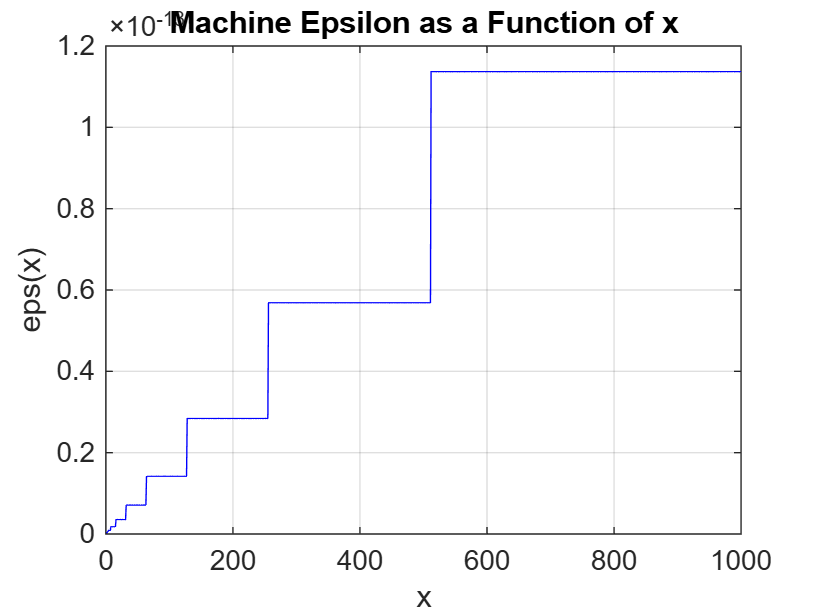

plot(x, y, 'b-'); % Plot eps(x) vs x
xlabel('x');
ylabel('eps(x)');
title('Machine Epsilon as a Function of x');
grid on;

   **The graph plots machine epsilon (eps(x)) as a function of x. As x increases, eps(x) remains constant for a range of values but doubles each time x crosses a power of 2. This occurs because, in floating-point representation, the exponent increases by 1 at each power of 2, which doubles the spacing between consecutive representable values. Between these jumps, eps(x) remains unchanged since the spacing between adjacent floating-point numbers is constant within a given exponent range. This results in the characteristic step-like structure seen in the plot.**

 b) Write your own function named *myeps(x)* to compute difference between x and the next higher number. Your function should take integer x as input and provide the  difference between x and the next higher number that can be stored in 64 bit floting point  reprsentation. Write your function in the appendix of this mlx file and test it in the cell below.

Test your function for  x = 1,2,3,4,5,…,1000. Plot the output of your function vs x, explain the results obtained.

% write your code here 
x = 1:1000

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y = myeps(x)

y = 1.0e-12 *

    0.0002    0.0004    0.0004    0.0009    0.0009    0.0009    0.0009    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0018    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071    0.0071


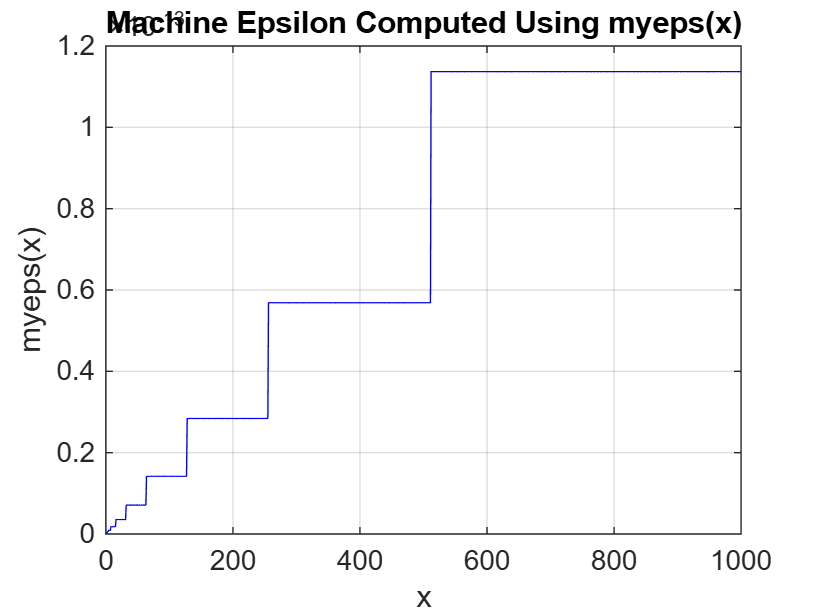

plot(x, y, 'b-');  % Plot myeps(x) vs x
xlabel('x');
ylabel('myeps(x)');
title('Machine Epsilon Computed Using myeps(x)');
grid on;

` c) `The relative error due to rounding is defined as,

                                                            
$$\eta_x = \left| \frac{x - \hat{x}} {x} \right |$$


    where x is the actual value and $\hat{x}$ is the value stored as a  floating point number. Write a function to estimate the value of the relative error as a  function of the stored value, you may use the MATLAB function provided in part (a). 

Use $\hat{x}$ = 1,2,3,4,5,…,1000.  Plot $\eta_x$vs $\hat{x}$, explain the results obtained using your function.  Is there an upper bound for it?  If so what is it? 

% write your code here
x = double(1:1000);
y = relative_error(x)

y = 1.0e-15 *

    0.2220    0.2220    0.1480    0.2220    0.1776    0.1480    0.1269    0.2220    0.1974    0.1776    0.1615    0.1480    0.1366    0.1269    0.1184    0.2220    0.2090    0.1974    0.1870    0.1776    0.1692    0.1615    0.1545    0.1480    0.1421    0.1366    0.1316    0.1269    0.1225    0.1184    0.1146    0.2220    0.2153    0.2090    0.2030    0.1974    0.1920    0.1870    0.1822    0.1776    0.1733    0.1692    0.1652    0.1615    0.1579    0.1545    0.1512    0.1480    0.1450    0.1421


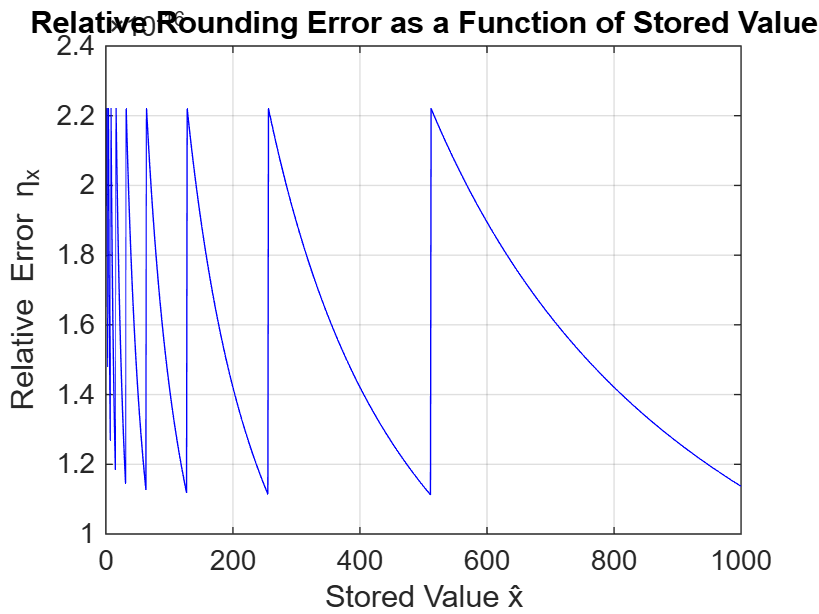

plot(x, y, 'b-');  % Plot eta_x vs x
xlabel('Stored Value x̂');
ylabel('Relative Error η_x');
title('Relative Rounding Error as a Function of Stored Value');
grid on;

**The plot of relative rounding error shows periodic spikes at powers of 2, caused by the doubling of **`eps(x)`** when the exponent increases. Between spikes, the error decreases hyperbolically as **`x`** grows, since **`eps(x)`** remains constant within each exponent range. The distance between spikes increases because powers of 2 grow exponentially. The upper bound on relative error is about eps(1)=2.22×10−16, confirming that floating-point precision maintains fixed relative accuracy rather than absolute precision.**

d) The MATALB function call `eps(‘single’)` computes the machine epsilon for single precision (32bit) floating point numbers.

  Using your knowledge of the floating-point representation find an expression that computes the output of that funciton.

**  As done in our tutorial, the machine epsilon will be 2^(- # of mantissa bits). In this example with single precision floating point numbers, the mantissa is 23 bits. Therefore, the machine epsilon for single precision floating point numbers is 2^(-23).**

## Question 4: Round off errors (15 marks)

a) Given the equation $x^2 + 2 bx  -1=0$ where $b$ is a parameter chosen such that $b> 0$. Using the quadratic formula the roots $x_1$ and $x_2$ of this equation are given by $x=-b\pm\sqrt{b^2 +1}$ . The following MATLAB program computes and plots the roots $x_1$ and $x_2$ as a function of $b$ for 1000 logarithmically spaced values of $b$ between ${10}^6$ and ${10}^8$. Run the code and explain the reason why there are discontinuities.

**If we rearrange x1 we get x1 = sqrt(b^2+1) - b. The reason for discontinuities in x1 is because we're subtracting two nearly equal large numbers, causing catastrophic cancellation. This causes a loss of precision, leading to discontinuities. If we rearrange x2, we get x2 = - (b + sqrt(b^2+1)). Because we're adding two nearly equal large numbers here, there is no catastrophic cancellation and thus, there are no discontinuities in the plot of x2 vs b. **

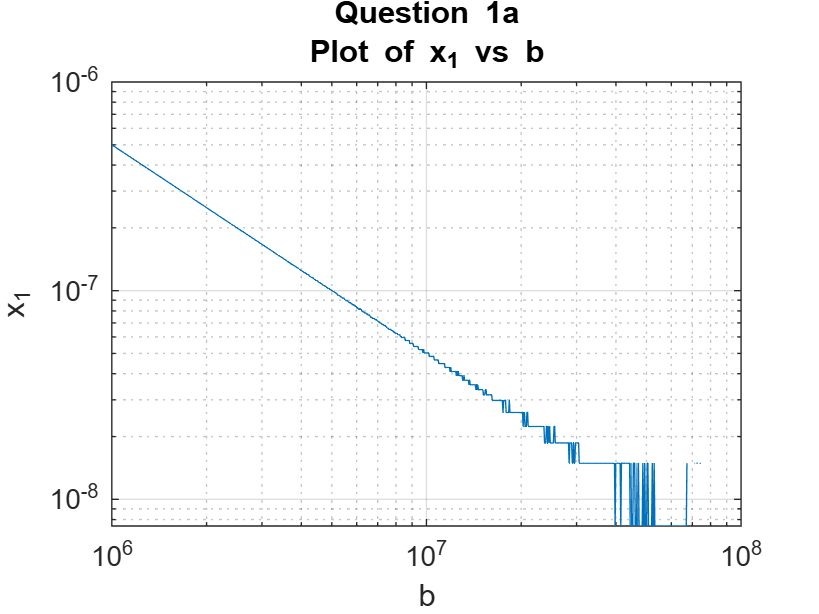



b = logspace(6,8,1000);

x1 = -b+sqrt(b.^2 +1);
x2 = -b-sqrt(b.^2 +1);



%plot x1 on a loglog scale

figure
loglog(b,x1)
title({'Question 1a';'Plot of x_1 vs b'})
xlabel('b')
ylabel('x_1')
grid on

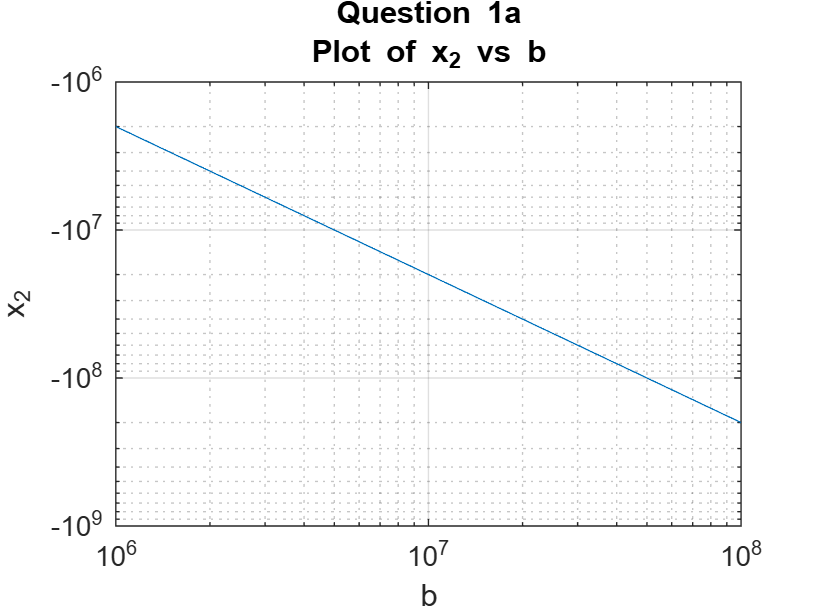



%plot x2 on a loglog scale

figure
loglog(b,x2)
xlabel('b')
ylabel('x_2')
title({'Question 1a';'Plot of x_2 vs b'})
grid on

b)  For the part a) one of the obtained roots is $x_1 = -b + \sqrt {b^2 +1}$ .  When using 64-bit IEEE number representation (double precision) what is  the smallest value of  $b$  the result of the computation $x_1 = -b + \sqrt {b^2 +1}$ produces an answer $x_1 =0$? Explain.

**In 64-bit double precision, the relative precision is approximately 2^(-52), meaning the spacing between representable numbers near a value X is around X * 2^(-52). For the expression b^2 + 1, when b is very large, b^2 dominates, and the spacing becomes roughly b^2 * 2^(-52). The value 1 in b^2 + 1 becomes insignificant when 1 is less than b^2 * 2^(-52). Solving for b gives b^2 > 2^(52), which means b > 2^(26). Since 2^(26) is about 67 million, for b greater than 67,108,864, the computer can no longer distinguish the 1 in b^2 + 1, effectively rounding it to b^2. As a result, the calculation for x1 = -b + sqrt(b^2 + 1) simplifies to 0 due to catastrophic cancellation.**

d) Write a script that computes and plots the roots $x_1$ and $x_2$ as a function of $b$ for 1000 logarithmically spaced values of $b$ between ${10}^6$ and ${10}^8$ (same as in part a. above) which does not suffer from numerical illconditioning.

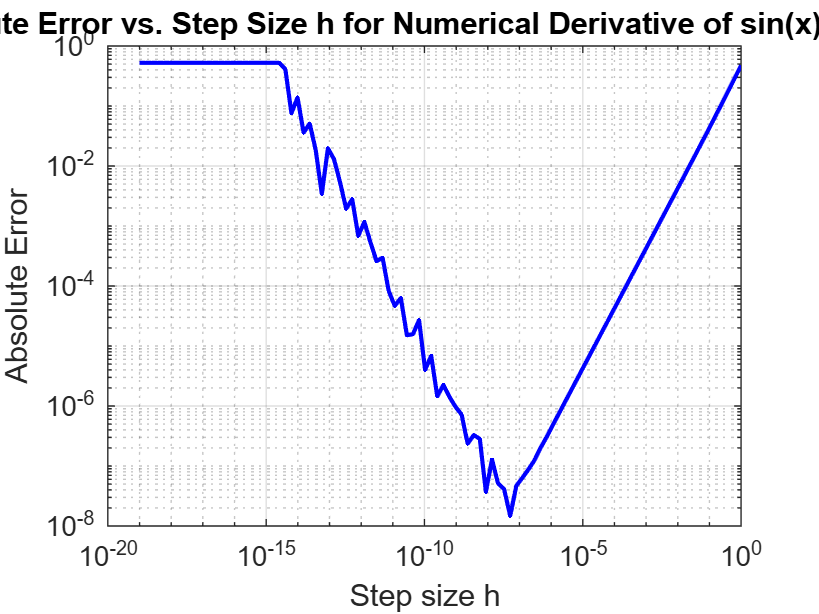

% write your program here 

b = logspace(6,8,1000);

%% Put your code for computing x1 and x2 below

% Compute x1 using numerically stable rearrangement by multiplying both the
% numerator and denominator by conjugate
x1 = 1 ./ (b + sqrt(b.^2 + 1));

% Compute x2 normally (x2 does not suffer from cancellation)
x2 = - (b + sqrt(b.^2 + 1));


%plot x1 on a loglog scale
figure(1)
loglog(b,x1)
xlabel('b')
ylabel('x_1')
grid on
title({'Question 1d';'Plot of x_1 vs b'})


%plot x2 on a loglog scale
figure(2)
loglog(b,x2)
xlabel('b')
ylabel('x_2')
grid on
title({'Question 1d';'Plot of x_2 vs b'})







## Question 5: Round-off Errors (5 marks)

We want to write a function for computing the function $y=\mathrm{s}\mathrm{i}\mathrm{n}\mathrm{h}\left(x\right)$ . One way to compute  is to use the following expression

                                                            
$$y=\sinh {\left(x\right)}=\frac{1}{2}{\left(e^x -e^{-x} \right)}\$$


What sort of numerical difficulties can we face if $x\approx 0$? Can you suggest a way to overcome the difficulties we may face near $x\approx 0$ ? (Hint: $e^x$ can be approximated using a Taylor series). Discuss and quantify any other types of error that your proposed approach may introduce.

**When x is about zero, we can encounter catastrophic cancellation due to subtraction of two nearly equal numbers. To avoid this, we use the Taylor series approximation:**

**sinh(x) ≈ x + x^3/6 + x^5/120 (let's say we omit the next term for cpu cost)**

**which introduces a truncation error by ignoring the next term, x^7/5040. For small x, this error is negligible—about 1.98 × 10⁻²⁴ for x = 10⁻³. However, as x increases, the error grows: at x = 0.1, it is 1.98 × 10⁻¹¹, and at x = 1, it reaches 1.98 × 10⁻⁴. Thus, the Taylor approximation is highly accurate for small x, but for larger values, additional terms may be needed for precision.**

## Question 6: (15 Marks)

The derivative of a function, f(x), can be computed using the finite difference method, which can be derived using the first-order terms of the Taylor series expansion of the function, about : 

$f{\left(x_0 +h\right)}=f{\left(x_0 \right)}+hf^{\prime } {\left(x_0 \right)}+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^3 +\ldots$                    (4.1)

Rearranging terms to solve for $f^{\prime } {\left(x_0 \right)}$  and ignoring (truncating) the higher-order terms, we obtain the first order approximation of derivative

$f^{\prime } {\left(x_0 \right)}\;\approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 \right)}}{h}$                                                                          (4.2)

(a) What is the truncation error for the above approximation? How does the trunction error behave with decrease in the value of $h$ ?

**when we rearrange for f'(x0) in eq 4.1, we get f'(x0) = (f(x0 + h) - f(x0))/h - (1/2!)*f''(x0)h - (1/3!)*f'''(x0)h^2..., and so on. When we look at equation 4.2, we only keep the first term of the equation, so the truncation error is the first term that was ignored, or +/-(1/2!)*f''(x0)h.  When h decreases, the truncation error also decreases proportionally to h.**

(b) To compute the derivative of $f (x) = sin(x)$, we can use the equation (4.2) as,

                        $\frac{d sin(x)} {dx}  \approx$ $\frac{\sin {\left(x+h\right)}-\sin {\left(x\right)}}{h}$                                                                                                   (4.3)

 In the cell below, write a MATLAB program that can compute the derivative of the $sin(x)$ at $x=45$ for different values of $h$. Use $h=10^{-19},10^{-18}, 10^{-17} ,..., 10^{-2}, 10^{-1}, 1$.

We know the true value of derivative of $sin(x)$ at $x=45$ is $cos(45)$. Plot the absolute error vs $h$.  Make sure the axis are labeled and the plot has an appropriate title.

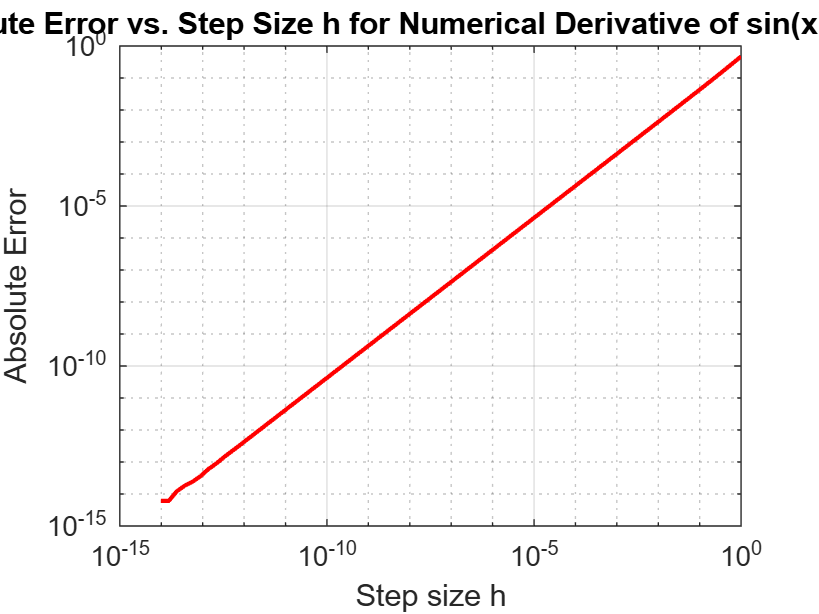

% write your code here.

h = logspace(-19,0,100);  % h is a vector here that contains 100 values between 10^(-19) to 1
% Define the function f(x) = sin(x) and its true derivative at x = 45
x0 = 45;  % Given x0 = 45
f = @(x) sin(x);       % Function: sin(x)
true_derivative = cos(x0); % True derivative of sin(x) at x0 = 45

% Compute numerical derivative using forward difference formula
numerical_derivative = (f(x0 + h) - f(x0)) ./ h;

% Compute absolute error

absolute_error = abs(numerical_derivative - true_derivative);

% Plot absolute error vs. h
figure;
loglog(h, absolute_error, 'b-', 'LineWidth', 1.5);
xlabel('Step size h');
ylabel('Absolute Error');
title('Absolute Error vs. Step Size h for Numerical Derivative of sin(x) at x = 45');
grid on;



(c) The function $sin(x+h)-sin(x)$ can be transformed into another form  using the trigonometric formula

$sin(\phi) - sin(\psi) = 2 cos(\frac{\phi+\psi}{2}) sin((\frac{\phi-\psi}{2})$                                                                                                    (4.4)

Using the above formula, transform the equation (4.3) to compute the derivative of $sin(x)$ and write a MATLAB program that computes the derivative of the $sin(x)$ at $x=45$ for $h=10^{-19},10^{-18}, 10^{-17} ,..., 10^{-2}, 10^{-1}, 1$.

Compare the derivative obtained with the true value and plot the absolute error vs $h$.  Make sure the axes are labeled and the plot has an appropriate title.

% write your code here.

h = logspace(-19,0,100);  % h is a vector here that contains 100 values between 10^(-19) to 1
% Define the function and its true derivative at x = 45
x0 = 45;  % Given x0 = 45
true_derivative = cos(x0); % True derivative of sin(x) at x0 = 45

% Compute numerical derivative using the transformed equation
numerical_derivative = cos(x0 + h/2);


Elapsed time is 0.003990 seconds.


% Compute absolute error
absolute_error = abs(numerical_derivative - true_derivative);


Error1 = single
5.1897e-08

% Plot absolute error vs. h
figure;
loglog(h, absolute_error, 'r-', 'LineWidth', 1.5);
xlabel('Step size h');
ylabel('Absolute Error');
title('Absolute Error vs. Step Size h for Numerical Derivative of sin(x) at x = 45');
grid on;



(d) Explain the difference in accuracy between the results obtained in part (b) and (c). 

**The difference in accuracy between part (b) and part (c) is due to how each method handles small h. In part (b), the standard finite difference method suffers from catastrophic cancellation because sin (x+h) and sin (x) are nearly equal for small h, leading to a loss of precision and unstable oscillations in the error. This results in an initial decrease in error, followed by a sharp increase due to floating-point round-off errors. In contrast, part (c) uses a trigonometric identity to avoid direct subtraction, preventing catastrophic cancellation. As a result, the error decreases smoothly without instability, making part (c) significantly more accurate and numerically stable than part (b).**

## Question 7: (25 Marks)

In this question you are tasked with computing the sum of the elements in a vector. 

a) Run the following code cell to compute the sum of the elements in a vector. Explain the discrepancy between the results obtained with MATLAB's in built function and the analytical solution. 

**The discrepancy arises because the single precision sum introduces rounding errors with each addition, and these errors accumulate over 30 million numbers. In contrast, double precision maintains higher accuracy, making it more reliable as the ground truth. The observed relative error (~5.19 × 10⁻⁸) is consistent with the expected behavior of single precision floating-point arithmetic.**

N = 30000000;
rng(200);                 % select random seed for reproducible resutls
XL = normrnd(1,0.1,N,1);  % Generate normal random numbers
X  = single(XL);          % Convert to single precision float

D_sum = sum(XL);  % We use the double precision sum as the "exact" ground truth.

tic

Elapsed time is 0.053049 seconds.


S1 = sum(X); % use in built MATLAB function to compute the sum
toc

Error2 = single
3.0919e-05



Error1 = abs(D_sum-S1)/D_sum  % compare the results

b) Write a function S = naiveSum(X) that incrementally computes the sum of the values $x_1$, $x_2$, ..., $x_n$ incrementally:


$$S_1 = x_1 $$



$$S_2 = S_1 + x_2$$



$$\vdots$$



$$S_n = S_{n-1} + x_n$$


This can be implmented using a for-loop in matlab.

Test your function using the following code:

N = 30000000;
rng(200);                 % select random seed for reproducible resutls
XL = normrnd(1,0.1,N,1);  % Generate normal random numbers
X  = single(XL);          % Convert to single precision float

D_sum = sum(XL);  % We use the double precision sum as the "exact" ground truth.

tic
S2 = naiveSum(X); % use your function to compute the sum
toc

Elapsed time is 7.275642 seconds.



Error2 = abs(D_sum-S2)/D_sum  % compare the results

Error3 = single
5.1897e-08

c) Write a function S =  *rSum(X) *that uses recursion to compute the sum of the elements provided in the vector X.  This approach is summarized as follows,


$$S(X) = 
     \begin{cases}
       0 &\quad  \text{if   } n=0 \\
       x_1 &\quad \text{if   } n=1  \\
     S(X(1:n/2))+S(X(n/2 +1 : n) &\quad\text{if   } n>1 \\ 
     \end{cases}$$


Note that $n$ is the number of elements in X. Also be careful to address the case where $\frac{n}{2}$ is not an integer. Use the following code to test your function.

N = 30000000;
rng(200);                 % select random seed for reproducible resutls
XL = normrnd(1,0.1,N,1);  % Generate normal random numbers
X  = single(XL);          % Convert to single precision float

D_sum = sum(XL);  % We use the double precision sum as the "exact" ground truth.

tic
S3 = rSum(X); % use your function to compute the sum
toc

Elapsed time is 0.057040 seconds.



Error3 = abs(D_sum-S3)/D_sum  % compare the results

Error4 = single
1.4771e-08

d) The recursive function calls add a significant amount of cpu cost in the algorithm in part c. Propose, implement, and test a compromise algorithm using both the naive and recursive approach that has both good accuracy and good cpu cost. Compare your algorithm to the MATLAB function sum. Explain your design decision for the proposed algorithm. Test your algorithm in the following code cell:


N = 30000000;
rng(200);                 % select random seed for reproducible resutls
XL = normrnd(1,0.1,N,1);  % Generate normal random numbers
X  = single(XL);          % Convert to single precision float

D_sum = sum(XL);  % We use the double precision sum as the "exact" ground truth.

tic
S4 = improvedSum(X); % use your function to compute the sum
toc 

Error4 = abs(D_sum-S4)/D_sum  % compare the results

**The proposed algorithm, **`improvedSum`**, combines naive and recursive summation to balance accuracy and CPU efficiency. The input vector **`X`** is split into chunks of 100,000 elements, allowing efficient processing within each chunk using the **`naiveSum`** function. The partial sums from these chunks are then recursively combined using the **`rSum`** function, which improves numerical stability by minimizing rounding errors. This approach reduces the overhead of deep recursion while maintaining high accuracy. Compared to MATLAB’s built-in **`sum`** function, **`improvedSum`** offers competitive accuracy with improved performance over pure recursion, though MATLAB’s **`sum`** remains faster due to its optimized implementation.**

e) Explain the difference in accuracy and cpu cost for the above methods for computing the sum. 

**The comparison of the different methods highlights clear trade-offs between accuracy and CPU cost. While the improved algorithm achieves high accuracy and significantly reduces computation time compared to the pure recursive method, MATLAB’s built-in sum function can still be considered the best overall. It offers unmatched performance due to its highly optimized low-level implementation, making it the fastest among all methods tested. Additionally, it maintains consistently low error, with only marginal differences in accuracy compared to the improved algorithm. Given its speed, reliability, and efficiency, MATLAB’s sum function remains the preferred choice for most applications, effectively balancing both performance and numerical stability.**

## Appendix

Write your functions here.

### Write code for Question 2 here

function out= myeps(x)

    %write your code here
    bits = typecast(x, 'uint64');  % Get raw IEEE 754 bit representation
    next_bits = bits + 1;          % Increment by 1 (next representable number)
    next_x = typecast(next_bits, 'double');  % Convert back to floating point
    out = next_x - x;              % Compute difference

end

function eta = relative_error(x)
    eta = eps(x) ./ x;  % Element-wise division to get relative error
end


###  Write functions for Question 7 here.

function S = naiveSum(X)
% returns the sum of all elements in vector X
    S = 0;

    for i = 1:length(X)
        S = S + X(i);
    end

end

%--------------------------------------------------------------------------

function S = rSum(X)
% Returns the sum of all elements in vector X using the recurssion
    n = length(X);
    if n == 0
        S = 0;

    elseif n == 1
        S = X(1);

    else
        mid = floor(n / 2);  % Find the middle index
        S = rSum(X(1:mid)) + rSum(X(mid+1:end));  % Recursive calls
    end
end

%--------------------------------------------------------------------------
function S = improvedSum(X)
% Returns the sum of all elements in vector X
    chunk_size = 100000;  % Size of each chunk
    n = length(X);

    % If the array is small enough, directly use naiveSum
    if n <= chunk_size
        S = naiveSum(X);
        return;
    end

    % Split the array into chunks
    num_chunks = ceil(n / chunk_size);
    partial_sums = zeros(1, num_chunks, 'like', X);  % Preallocate for efficiency

    % Apply naiveSum to each chunk
    for i = 1:num_chunks
        start_idx = (i - 1) * chunk_size + 1;
        end_idx = min(i * chunk_size, n);
        partial_sums(i) = naiveSum(X(start_idx:end_idx));
    end

    % Recursively sum the partial sums using rSum
    S = rSum(partial_sums);

end